# **3D visualisation of APT data**

The starting situation is a loaded pos file, loaded colorScheme, and a ranged mass spectrum (spec), see live script ***FirstSteps***.

If the start is here it have to be loaded a clolorScheme and a pos file. To load an ranged mass spectrum figure pull it in comandline and press run. Then select the the mass spectrum and enter: *spec = gco;*

load colorScheme.mat
pos = posToTable;

file   loaded


Error using fileparts (line 37)
Input must be a row vector of characters or string scalar.

Error in posToTable (line 25)
[~ , ~, ext] = fileparts(fileName);

## Extracting ions of the ranged mass spectrum

Then ranges must be extracted and the pos file needs to be parsed so that a column with *'ion'* is generated.

rng = rangesExtractFromMassSpec(spec);
options = 'decompose'

options = 'decompose'

pos = posAllocateRange(pos, rng, options);
 

## Plotting 3D-Data

For the subsquent 3D visualisation, the function *scatterPlotPosData* is needed.

*[p, ax] = scatterPlotPosData(pos,species,sample,colorScheme,size,plotAxis);*

### *Plotting of one species*

species = 'C' % which ion/atom species should be plotted; one single ion {'X'}

species = 'C'

sample = 1 % allows the specification of a subset to plot. If sample <1, it is a fraction of the overall number of atoms, if >1, it is a fixed number.

sample = 1

size = 1% size of the single atoms in the plot

size = 1

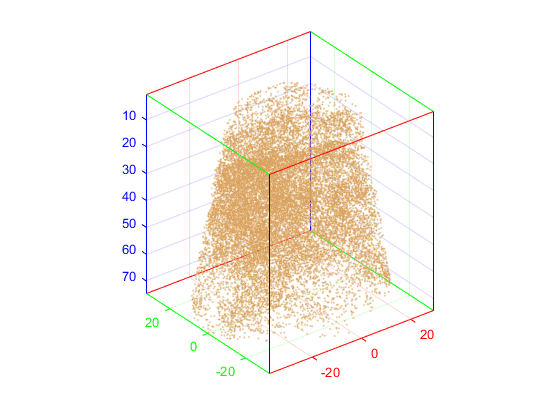

[p, ax] = scatterPlotPosData(pos,species,sample,colorScheme,size);

### Plotting of more species in more plots

species = {'C','Mn'} % which ion/atom species should be plotted; more ions {'X','Y','Z'}

species = 1×2 cell array
    {'C'}    {'Mn'}


sample = 1 % allows the specification of a subset to plot. If sample <1, it is a fraction of the overall number of atoms, if >1, it is a fixed number.

sample = 1

size = 1% size of the single atoms in the plot

size = 1

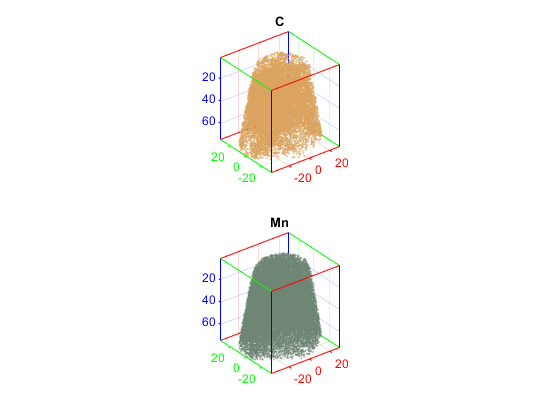

[p, ax] = scatterPlotPosData(pos,species,sample,colorScheme,size);

### Plotting of more species in one plot

For plotting atoms in **one plot **(with plotAxis input): *[p, ax] = scatterPlotPosData(pos, species, sample, colorScheme, size, ****axes(figure())****);*

species = {'C','Mn'} % which ion/atom species should be plotted; more ions {'X','Y','Z'}

species = 1×2 cell array
    {'C'}    {'Mn'}


sample = 1 % allows the specification of a subset to plot. If sample <1, it is a fraction of the overall number of atoms, if >1, it is a fixed number.

sample = 1

size = 1% size of the single atoms in the plot

size = 1

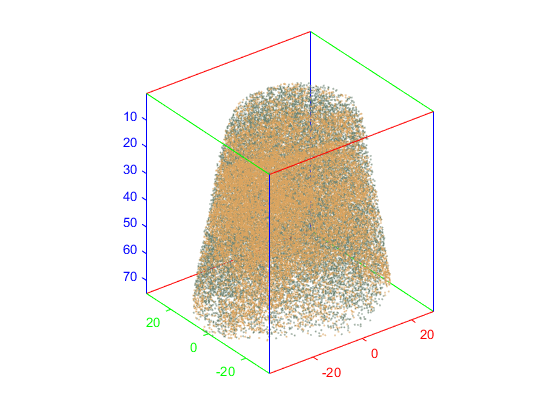

[p, ax] = scatterPlotPosData(pos,species,sample,colorScheme,size,axes(figure()));